## **ZÁŘENI ZÁKLADNÍ ZÁKONY**

#### prof. Ing. Josef STETINA, Ph.D. / Vysoké učení technické v Brně

#### email: josef.stetina@vutbr.cz

#### www: http://termomechanika.online/

**PLANCKŮV VYZAŘOVACÍ ZÁKON**

Tepelné záření o frekvenci *f = c/**l*[Hz] může být vyzařováno nebo pohlcováno jen po kvantech energie o velikosti *e = **h.f*  [J].

*h* = 6,6256.10-34[J.s]  je Planckova konstanta.

**MATEMATICKÁ FORMULACE PLANCKOVA ZÁKONA **- Plyne ze slovní formulace a definuje spektrální hustotu zářivého toku černého tělesa


$$\[{E_{0\lambda }} = \frac{{{c_1} \cdot {\lambda ^{ - 5}}}}{{exp\left( {\frac{{{c_2}}}{{\lambda  \cdot T}}} \right) - 1}}\]$$


*c**1** = c**2**.h*

*c**1** =* 3,74.10-16W.m2

c2 = 1,44.10-2K.m


$$${E_{0\lambda }} = f(\lambda ,\;T)$$$


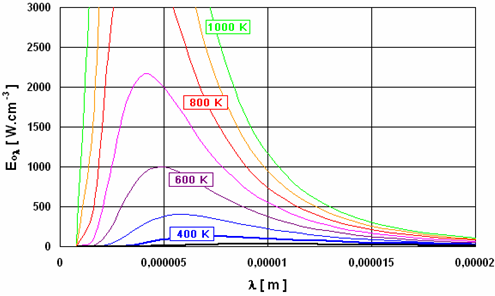

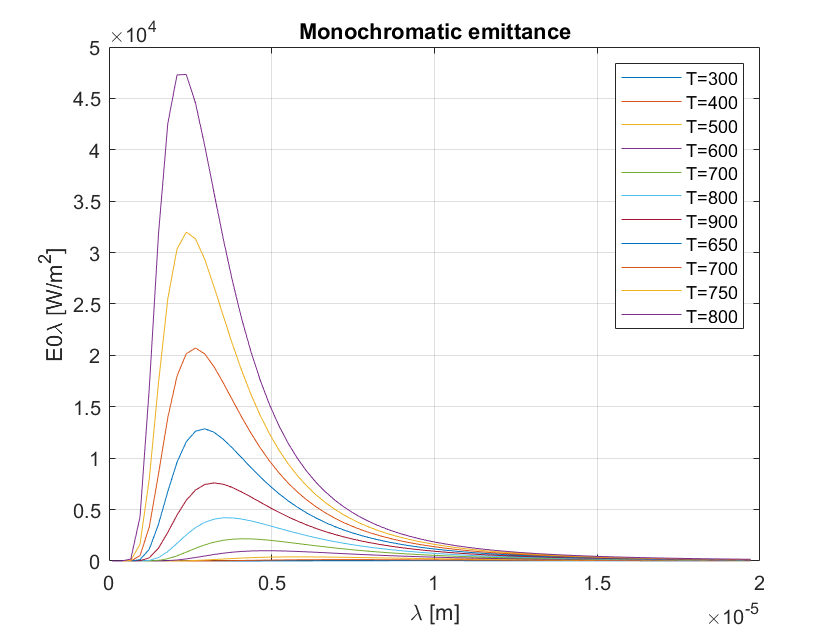

% Speed of light in a vacuum
c0 = 2.99792458*10.^8; % (±1.2) m/s 
% Planck's constant
h = 6.626176*10.^-34; % (±0.000036·10^-34) W·s^2 
% Boltzman constant
k = 1.380662*10.^-23; % (±0.000044·10^-23) W·s/K
% Refravtive index of the medium.
n = 1;
% Defining two new constants
% c1 = 2·pi·h·c0^2 (first radiant constant)
c1 = 3.741832*10^-16; % (±0.000020·10^-16) W·m^2 
% c2 = h·c0/k (second radiant constant)
c2 = 1.438786*10^-2; % (±0.000045^-2) m·K  
%   References
%   [1] W. Minkina and S. Dudzik, "Infrared Thermography," John Wiley & Sons
%   2009
% Convert the wavelength in micrometers (µm, 10^-6 m)
%lamda = lamda * 10^-6;
step=  2.8429e-007;
lamda=[10.^-7:step:2*10.^-5];
for T=300:100:1300
% Calculate the spectral radiant exitance in(W/m^2·µm)
 M = (10^-6 .* c1) ./ ((n.^2) .* lamda.^5 .* (exp(c2./(lamda * T))-1));
 lmax = 2.88e-3./T;
plot(lamda,M)
hold on
grid
end
xlabel('\lambda [m]')
ylabel('E0\lambda [W/m^2]')
title('Monochromatic emittance')
legend('T=300','T=400','T=500','T=600','T=700','T=800','T=900','T=650','T=700','T=750','T=800')
hold off

### Lokální funkce 

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí 

function [m] = km2m(km)
m = km*1000.0;
end

Převod

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end

Převod

function [C] = K2C(K)
C = K-273.15;
end